## Task 1: Control accomodation

Control accomodation is the important first step that ensures near linear behaviour of the vehicle actuation. It consists of thruster nonlinearity compensation and control allocation.

### 2.1.1 Thruster nonlinearity compensation

Your first step is to create a dataset mapping input PWM commands to achieved force. In the *single_thruster.slx* Simulink file, shown below, the thruster model is isolated for individual testing. The same thruster model is used for the H2OmniX simulation.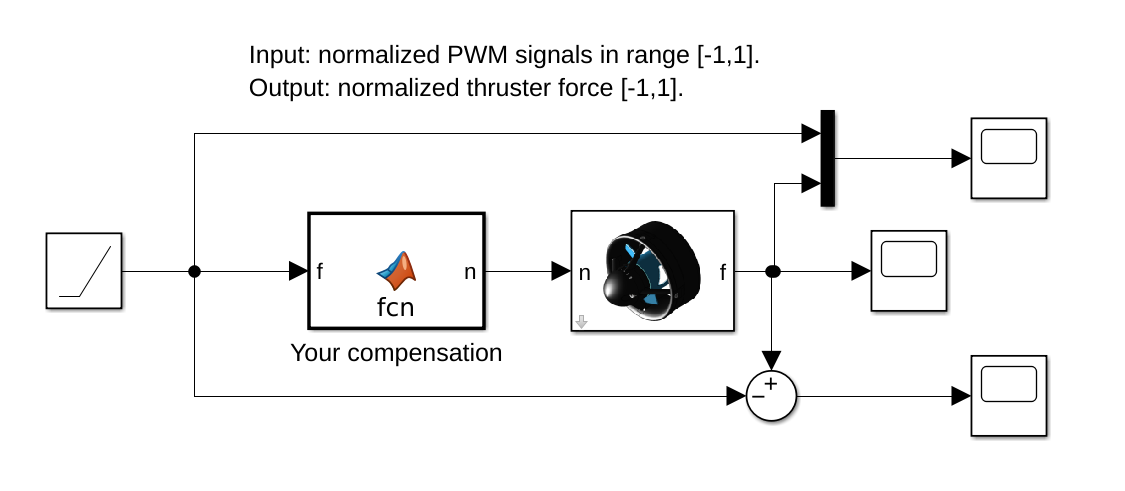

You can access the used data by looking under the mask of the T200 Simulink block. There you will find two constant vectors for PWM and corresponding force. You can use these vectors as the dataset. Once you extracted the dataset use the MATLAB cftool to find the corresponding mapping of control commands into PWM signals for the thruster.

**Hint:** you can either find the polynomial function f which gives you forward mapping F = f(PWM) and then find an inverse solution. Alternatively, you can map directly the inverse and find g which gives you PWM = g(F). Either way, keep in mind that: a) it is not necessary to overfit, and b) when no forces requested you should output zero, c) you should always limit the entry into your function to the range of values that you fitted data on (to avoid bad extrapolations).

**Put in the report the following:**

**1. PWM vs. Force plot of your dataset. Comment on the shape. Is it already linear or not?**

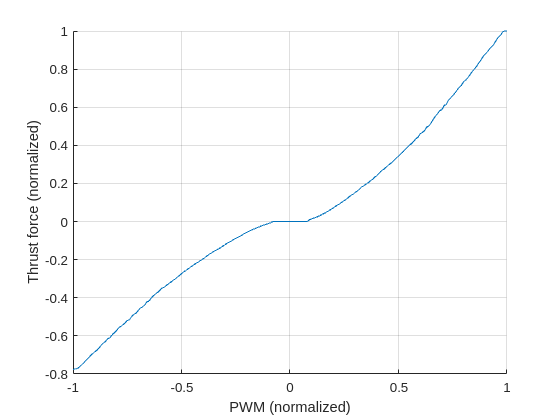

% Answer: The shape is not linear. Additionally, there is an apparent
% deadzone in of the thrusters located between ~ <-0.1,0,1>.
load t200_data.mat;

figure;
hold on;
grid on;
plot(pwm, F);
xlabel('PWM (normalized)');
ylabel('Thrust force (normalized)');

**2. Comment which function can approximate Force vs. PWM curve and why you selected it.  **Specify the function parameters received using the **cftool** or similar 

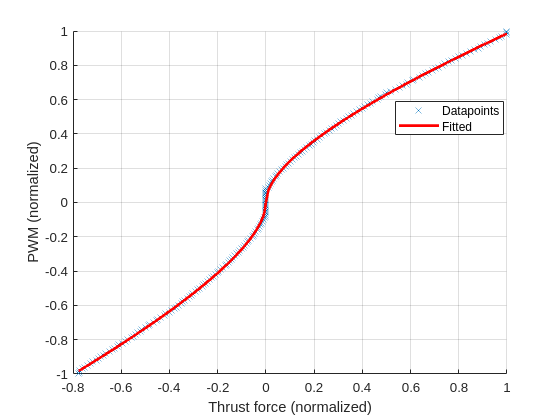

% I used cftool to fit the function PWM=f(F). A custom shape was used: a*x
% + b*x^0.5 for positive and -a*x + b*(-x)^0.5 due to its apparent square shape. With this fit the dead zone is ignored,
% but could be added if required. The general fit can be seen on the plot below. While the fit curves can
% be seen in the positive_fit.fig and negative_fit.fig. The inverse can be
% implemented in Simulink as a matlab function.

% Positive values
ap=0.3252;
bp=0.6596;

% Negative values
an=-0.4509;
bn=-0.7176;

figure;
hold on;
grid on;
plot(F,pwm, 'x');
ylabel('PWM (normalized)');
xlabel('Thrust force (normalized)');

Fp = F(find(F>=0));
Fn = F(find(F<=0));

plot(Fp, ap*Fp+bp*sqrt(Fp), 'r', 'LineWidth',2);
plot(Fn, -an*Fn+bn*sqrt(-Fn), 'r', 'LineWidth',2);
legend('Datapoints', 'Fitted', 'Position', [0.70595,0.67817,0.19464,0.082143])

### 2.1.2 Control allocation

Your second step is to determine the control allocation which maps the generalized forces and torques (τ ) into thruster specific commands. In case of the H2OmniX vehicle these are four PWM commands. The H2OmniX thruster configuration (shown below). 

**Hint:** Implement the control allocation into a matlab function rather than directly into Simulink. You can then use the same function from within Simulink and within the *control_allocation_coverage.m* script.

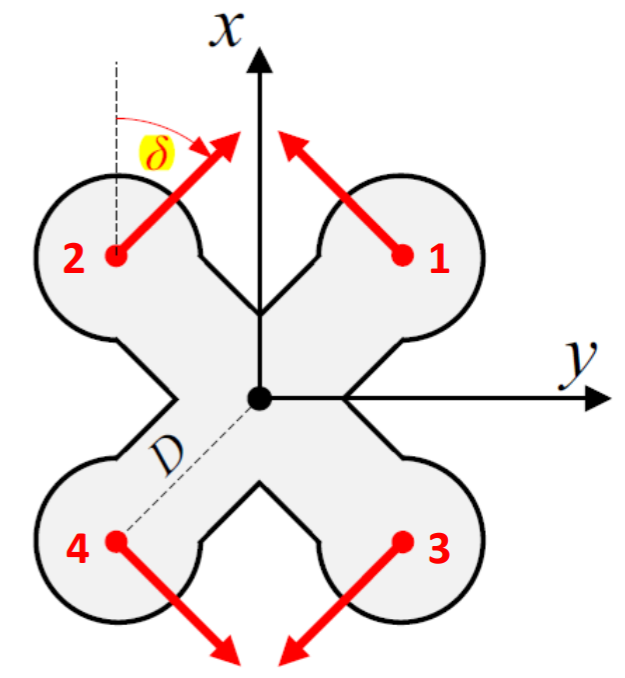

**Put in the report the following:**

**1. The actuator allocation B determined from figure above.**

% This matrix maps tau to thruster forces. The mapping is selected such that
% for ideal maximum thruster usage (abs(F)=1) the maximum surge, sway forces and
% yaw torques are 1.
B=[0.25, 0.25, -0.25, -0.25; -0.25,  0.25, -0.25,  0.25; -0.25, 0.25, 0.25, -0.25]

B =     0.2500    0.2500   -0.2500   -0.2500
   -0.2500    0.2500   -0.2500    0.2500
   -0.2500    0.2500    0.2500   -0.2500


**2. Describe the control allocation (inverse of actuator allocation) method you selected to calculate B†.**

% The pseudo inverse allocation was selected as it is most straight forward
% and the coverage is enough for the pool requirements. For better
% performance a cascade allocation mechanism can be considered.
Binv = pinv(B)

Binv =     1.0000   -1.0000   -1.0000
    1.0000    1.0000    1.0000
   -1.0000   -1.0000    1.0000
   -1.0000    1.0000   -1.0000


**3. Compare the coverage of your method in the X-Y space using the **`control allocation coverage.m `**script and attach the corresponding image. Comment on the coverage. You can use the function description to see the usage.**

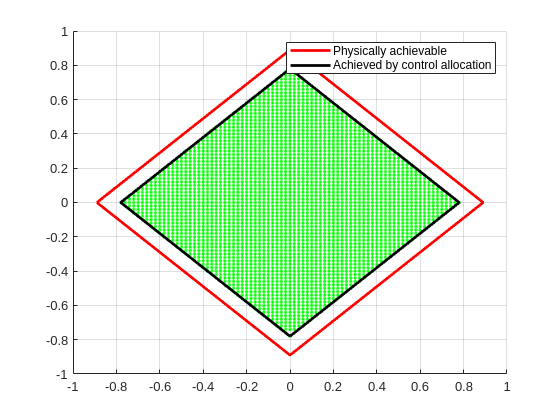

% The coverage is smaller than achievable but still most of the region is
% covered by the simple pseudoinverse. It is not realistic that in the pool
% we will need to operate at maximum powers. However, for field operation
% it might be useful to use another method.
control_allocation_coverage(@pinv_alloc)